# 271 Final Project 

# Autotuner 

by Aleksandra Koroza and Sydney Milo 

#### Overview

We have attempted to create an autotuner for our final project. Our code records the user for three seconds and outputs corrected pitches. This was accomplished by using MATLAB's built in pitch() function for pitch estimations and noise removal. We then find the note closest to each of the user's estimated pitches and play them out for the user. Pitch estimations are plotted and corrected notes are displayed after the program is run.

Since our project is designed to give immediate feedback after recording, we included our examples in the video instead of in the documentation section. When using it at home, we recommend being loud and getting relatively close to the microphone, since the program thresholds to avoid picking up irrelevant noise. This Autotune Live Script is the only file you will need to open.

Please note that MatLab will ask you to download an audio toolkit (Simulink) before it will allow you to use the "pitch" function in this project.

#### Recording

Audio is recorded using an audiorecorder object. Sampling frequency is specfied as fs.

recObj = audiorecorder(44100,8,1);

disp('Start singing.')

Start singing.


recordblocking(recObj, 3);
disp('That was terrible.');

That was terrible.



y = getaudiodata(recObj);
fs = 44100;
audioIn= y;

#### Pitch Estimations

The first set of plots display the recorded raw audio and pitch estimations using the pitch() function. This function estimates the fundamental frequency of an audio signal for overlapped analysis windows. PEF (pitch estimation filter) is the default method used and it served us well for our purposes. Other methods of calculating pitch exist such as SRH (Summation of Residual Harmonics) and LHS (Log Harmonic Summation). More information can be found in MATLAB [documentation](https://www.mathworks.com/help/audio/ref/pitch.html). 

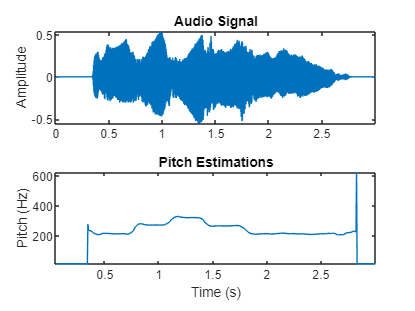

%Estimate pitch for singing voice
t = (0:size(audioIn,1)-1)/fs;

winLength = round(0.05*fs);
overlapLength = round(0.045*fs);
[f0,idx] = pitch(audioIn,fs,'Method','PEF','Range',[15,800],'WindowLength',winLength,'OverlapLength',overlapLength);
tf0 = idx/fs;

figure(1)
tiledlayout(2,1)

nexttile
plot(t,audioIn)
ylabel('Amplitude')
title('Audio Signal')
axis tight

nexttile
plot(tf0,f0)
xlabel('Time (s)')
ylabel('Pitch (Hz)')
title('Pitch Estimations')
axis tight

Pitch estimations are only valid if there is a harmonic component. The harmonic ratio (hr) is used to identify regions of noise or silence. 

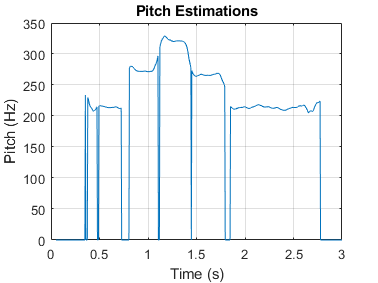

%Use the harmonic ratio as the threshold for valid pitch decisions. 
% If the harmonic ratio is less than the threshold, set the pitch decision to 0. 

hr = harmonicRatio(audioIn,fs,"Window",hamming(winLength,'periodic'),"OverlapLength",overlapLength);

threshold = 0.9;
f0(hr < threshold) = 0;


figure(2)
plot(tf0,f0);
xlabel('Time (s)');
ylabel('Pitch (Hz)');
title('Pitch Estimations');
grid on;

#### Corrected Pitches

We then play out the corrected pitches and display the audio output to the user. The functions required to make this work are explained in later sections. 

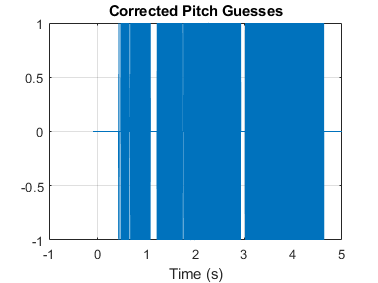

FS=44100;
deltat=1/FS;
t=[-0.1:deltat:5];
[noteNam,fixedFrequencies]=makeRect(tf0,1,f0,getNotes());
fixed=fixedFrequencies(1:224911);

figure(3);
plot(t,fixed);
xlabel('Time (s)');
title('Corrected Pitch Guesses');
grid on;

soundsc(fixedFrequencies,44100);

%disp(noteNam.');

[clean,lengths] = stringCleaning(noteNam);

for n=1:length(clean)
    str1=sprintf("Note %d",n);
    str2=sprintf(clean(n));
    str3=sprintf("For %d seconds",lengths(n));
    disp(str1);
    disp(str2);
    disp(str3);
    disp("");
end

Note 1


silent (N/A)


For 2.006229e+02 seconds


Note 2


 A#3/Bb3 


For 3.288900e+00 seconds


Note 3


silent (N/A)


For 1.315560e+01 seconds


Note 4


 A#3/Bb3 


For 6.577800e+00 seconds


Note 5


A3


For 1.644450e+01 seconds


Note 6


 G#3/Ab3 


For 3.946680e+01 seconds


Note 7


A3


For 3.288900e+00 seconds


Note 8


silent (N/A)


For 9.866700e+00 seconds


Note 9


A3


For 5.920020e+01 seconds


Note 10


 G#3/Ab3 


For 2.960010e+01 seconds


Note 11


A3


For 3.946680e+01 seconds


Note 12


 G#3/Ab3 


For 2.631120e+01 seconds


Note 13


silent (N/A)


For 5.262240e+01 seconds


Note 14


 C#4/Db4 


For 1.841784e+02 seconds


Note 15


D4


For 1.315560e+01 seconds


Note 16


silent (N/A)


For 9.866700e+00 seconds


Note 17


 D#4/Eb4 


For 9.866700e+00 seconds


Note 18


E4


For 8.222250e+01 seconds


Note 19


 D#4/Eb4 


For 9.866700e+00 seconds


Note 20


E4


For 5.920020e+01 seconds


Note 21


 D#4/Eb4 


For 3.288900e+01 seconds


Note 22


D4


For 1.315560e+01 seconds


Note 23


 C#4/Db4 


For 6.577800e+00 seconds


Note 24


silent (N/A)


For 3.288900e+00 seconds


Note 25


 C#4/Db4 


For 6.577800e+00 seconds


Note 26


C4


For 2.104896e+02 seconds


Note 27


B3


For 9.866700e+00 seconds


Note 28


silent (N/A)


For 3.617790e+01 seconds


Note 29


A3


For 9.866700e+00 seconds


Note 30


 G#3/Ab3 


For 6.906690e+01 seconds


Note 31


A3


For 2.960010e+01 seconds


Note 32


 G#3/Ab3 


For 3.617790e+01 seconds


Note 33


A3


For 1.249782e+02 seconds


Note 34


 G#3/Ab3 


For 1.545783e+02 seconds


Note 35


A3


For 1.644450e+01 seconds


Note 36


 G#3/Ab3 


For 9.866700e+00 seconds


Note 37


A3


For 6.248910e+01 seconds


Note 38


 G#3/Ab3 


For 5.920020e+01 seconds


Note 39


A3


For 3.946680e+01 seconds


Note 40


silent (N/A)


For 1.480005e+02 seconds


#### Finding Closest Frequency

The function findFreq() is used to match the user's estimated pitch to a list of known notes and their frequencies. The function getNotes() stores the possible notes and is used to print out the corrected pitches. 

function [bat,batIndex] = freqFinder(freq)

knownFreq = [16.35
    17.32
    18.35
    19.45
    20.6
    21.83
    23.12
    24.5
    25.96
    27.5
    29.14
    30.87
    32.7
    34.65
    36.71
    38.89
    41.2
    43.65
    46.25
    49
    51.91
    55
    58.27
    61.74
    65.41
    69.3
    73.42
    77.78
    82.41
    87.31
    92.5
    98
    103.83
    110
    116.54
    123.47
    130.81
    138.59
    146.83
    155.56
    164.81
    174.61
    185
    196
    207.65
    220
    233.08
    246.94
    261.63
    277.18
    293.66
    311.13
    329.63
    349.23
    369.99
    392
    416.3
    440
    466.16
    493.88
    523.25
    554.37
    587.33
    622.25
    659.25
    698.46
    739.99
    783.99
    830.61
    880
    932.33
    987.77
    1046.5
    1108.73
    1174.66
    1244.51
    1318.51
    1396.91
    1479.98
    1567.98
    1661.22
    1760
    1864.66
    1975.53
    2093
    2217.46
    2349.32
    2489.02
    2637.02
    2793.83
    2959.96
    3135.96
    3322.44
    3520
    3729.31
    3951.07
    4186.01
    4434.92
    4698.63
    4978.03
    5274.04
    5587.65
    5919.91
    6271.93
    6644.88
    7040
    7458.62
    7902.13];
placeholder=knownFreq;
freqLength = length(knownFreq);
sample=freq; %sets to sample frequency
i=cast(freqLength/2 + 0.5, 'uint32');
while(freqLength>1)
    freqLength=length(knownFreq);
    if (abs(knownFreq(i+1)-sample)<abs(knownFreq(i)-sample)) %move up
        %disp("up");
        knownFreq=knownFreq(i+1:end);
        freqLength=length(knownFreq);
        i=cast((freqLength/2), 'uint32');
    else %move down
        %disp("down");
        knownFreq=knownFreq(1:i);
        freqLength=length(knownFreq);
        i=cast((freqLength/2), 'uint32');
    end
    bat=knownFreq(1);
    if (bat~=0)
        batIndex=find(placeholder==bat);
    else
        batIndex=0; %index of zero means silence; no note sung
    end
end

end
function nanana = getNotes()
nanana=["C0";" C#0/Db0 ";"D0";" D#0/Eb0 ";"E0";"F0";" F#0/Gb0 ";"G0";" G#0/Ab0 ";"A0";" A#0/Bb0 ";"B0";"C1";" C#1/Db1 ";"D1";" D#1/Eb1 ";"E1";"F1";" F#1/Gb1 ";"G1";" G#1/Ab1 ";"A1";" A#1/Bb1 ";"B1";"C2";" C#2/Db2 ";"D2";" D#2/Eb2 ";"E2";"F2";" F#2/Gb2 ";"G2";" G#2/Ab2 ";"A2";" A#2/Bb2 ";"B2";"C3";" C#3/Db3 ";"D3";" D#3/Eb3 ";"E3";"F3";" F#3/Gb3 ";"G3";" G#3/Ab3 ";"A3";" A#3/Bb3 ";"B3";"C4";" C#4/Db4 ";"D4";" D#4/Eb4 ";"E4";"F4";" F#4/Gb4 ";"G4";" G#4/Ab4 ";"A4";" A#4/Bb4 ";"B4";"C5";" C#5/Db5 ";"D5";" D#5/Eb5 ";"E5";"F5";" F#5/Gb5 ";"G5";" G#5/Ab5 ";"A5";" A#5/Bb5 ";"B5";"C6";" C#6/Db6 ";"D6";" D#6/Eb6 ";"E6";"F6";" F#6/Gb6 ";"G6";" G#6/Ab6 ";"A6";" A#6/Bb6 ";"B6";"C7";" C#7/Db7 ";"D7";" D#7/Eb7 ";"E7";"F7";" F#7/Gb7 ";"G7";" G#7/Ab7 ";"A7";" A#7/Bb7 ";"B7";"C8";" C#8/Db8 ";"D8";" D#8/Eb8 ";"E8";"F8";" F#8/Gb8 ";"G8";" G#8/Ab8 ";"A8";" A#8/Bb8 ";"B8"];

end

#### Generating Sound 

We then use the found corrected pitches and generate sound using a series of cosine functions produced by the makeRect() function. 

function [sounds,newRect] = makeRect(t,progressIndex, arr, notes)
    newRect=zeros(1,300000);
    sounds=strings(1,592);
    FS = 44100;
    deltat = 1/FS;
    t=[-0.1:deltat:7];
    j=1;
    
    for k=progressIndex:length(arr)
        if (arr(k)>0) %if a pitch is detected
            for h=1:381
                [f,fi]=freqFinder(arr(k));
                newRect(j)=cos(2*pi()*f*t(j));
                j=j+1;
            end
            sounds(k)=notes(fi);
        else
            for h=1:381 %if no pitch detected (silence)
                newRect(j)=0;
                j=j+1;
            end
            sounds(k) = "silent (N/A)";
        end
    end
    
end

#### Removing Repeat Sections

This function cleans up repeated sections of notes and reports their duration in seconds. 

function [clean,lengths] = stringCleaning(strs)
cleaned=strings(1,length(strs));
noteLengths=zeros(1,length(strs));
addHere=1;

cleaned(1)=strs(1);


for r=2:(length(strs)-1)
    if ((~strcmp(strs(r),strs(r+1)))&&(~strcmp(strs(r-1),strs(r)))) %if neighboring strings are not the same
        noteLengths(addHere)=noteLengths(addHere)+3.2889;
        addHere=addHere+1;
        cleaned(addHere)=strs(r);
    elseif((strcmp(strs(r),strs(r+1)))&&(~strcmp(strs(r-1),strs(r))))%if next same and prev diff
        noteLengths(addHere)=noteLengths(addHere)+3.2889;
        addHere=addHere+1;
        cleaned(addHere)=strs(r);
       
    else %if subsequent string is the same
        noteLengths(addHere)=noteLengths(addHere)+3.2889; %count++
    end
end
noteLengths(addHere)=noteLengths(addHere)+(2*3.2889);

len=nnz(noteLengths);
lengths=noteLengths(1:len);
clean=cleaned(1:len);
end

#### Conclusion

We have been able to record sound, estimate sung pitches, and correct those pitches to a set of known notes. One way to build on our project is to make the output more closely resemble a human tone. We have also noted that the generated sound is somewhat choppy. 